Description:

To run the Cobra toolbox you need first to download the repository as indicated [at this link](https://opencobra.github.io/cobratoolbox/stable/installation.html). Your cobra folder should be included within the file code.

clc;
clear all;
close all;

%Paremeters
fontsize=15;%for plotting

%including all parent folders up to the file 'code', this makes visible all
%files within this code, which includes the COBRA toolbox you need first to
%download as follows from the intr
addingPathParentFolderByName('code');

Adding matlab path to: D:\code\bioelectrodynamics\code



initCobraToolbox(false) % false, as we don't want to update



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2026
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.49.0).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

%This lists all the versions of functions named initCobraToolbox in your matlab installation, after the current path, the version used is the first in this list.
which -all initCobraToolbox

D:\code\bioelectrodynamics\code\cobratoolbox~\initCobraToolbox.m


**Loading the model**

% Specify the MAT file you're looking for
% matFileName = 'model_aux.mat';
% matFileName = 'iMM904.mat';
matFileName = 'model_yeastGEM_v9_0_2.mat';
%place the current Matlab folder with the project files
cd(fileparts(which(matFileName)));
%load the model
model=readCbModel(matFileName);

Each model.subSystems{x} has been changed to a character array.



%% Find native "adder" motifs in a metabolic model (Yeast COBRA)
%
% Goal
% ----
% Identify places in the *existing* stoichiometric network (no model edits)
% where a metabolite mass-balance equation implies a relation of the form:
%
%   z = w1*v1 + w2*v2
%
% Interpretation in S*v = 0
% -------------------------
% For a metabolite m at steady state, COBRA enforces:
%   sum_j S(m,j)*v(j) = 0
%
% If metabolite m is produced by exactly two reactions r1 and r2 and consumed
% by exactly one reaction r3, and no other reactions involve m, then:
%
%   S(m,r1)*v1 + S(m,r2)*v2 + S(m,r3)*vz = 0
%   => vz = (S(m,r1)/(-S(m,r3)))*v1 + (S(m,r2)/(-S(m,r3)))*v2
%
% Here:
%   v1, v2 are the "input" fluxes (ideally single-gene-controlled reactions)
%   vz is the "output" flux (a consumer of m)
%   w1, w2 come directly from stoichiometric coefficients (native weights)
%
% Inputs required in workspace
% ---------------------------
%   model         : COBRA model struct containing fields S, rxns, mets, grRules
%   isSingleGene  : logical vector (numel(model.rxns) x 1), true if rxn has
%                   a single-gene GPR rule (computed earlier)
%   singleGeneID  : string vector (numel(model.rxns) x 1) gene id for each
%                   single-gene reaction (empty string otherwise)
%
% Output
% ------
%   Motifs : table listing candidate motifs with columns:
%            met, r1, r2, r3,
%            gene1, gene2,
%            gpr3, isSingleGene3, genes3
%
% Notes
% -----
% This script uses a *strict* criterion:
%   - metabolite participates in exactly 3 reactions total:
%       2 producers + 1 consumer
%   - both producers must be single-gene reactions (good control knobs)
% Reaction 3 (output) may be single-gene or multi-gene and is reported as such.

#### Mapping a 2 neurons network into the metabolic reaction

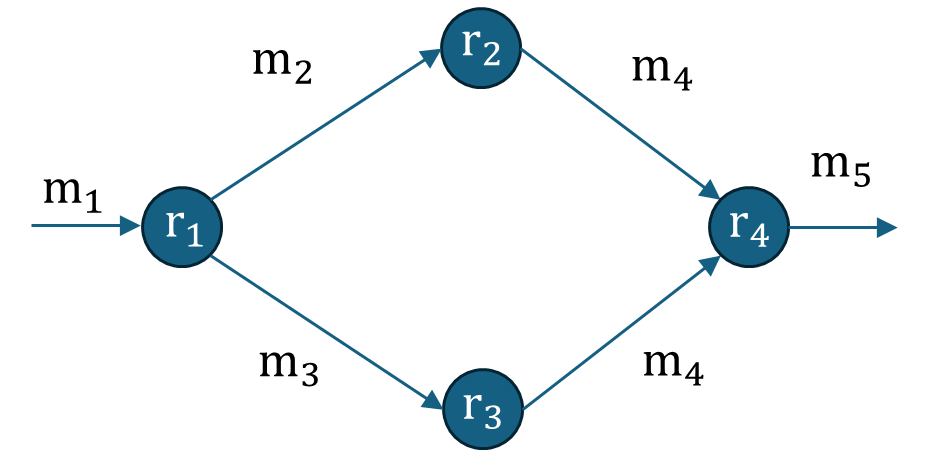

Fig. 1: 2-neurons NN.

**Algorithm:**

- **Step 1**: Look first for metabolites like $m_4$, that is produced by two different chemical reactions like $r_2$ and $r_3$ in Fig. 1. This is accomplished by looking on each row of the stochiometry matrix S the case where 2 coefficients are larger than zero, and one is less than zero. As illustrated in Fig. 2, such a row means that there are two chemical reactions $r_i$ and $r_j$ producing the metabolite of index $m$, as well as chemical reaction $r_k$ consuming it. That is, the chemical reactions $r_i$ and $r_j$ map to $r_2$ and $r_3$ in Fig. 1, while $r_k$ maps to $r_4$.

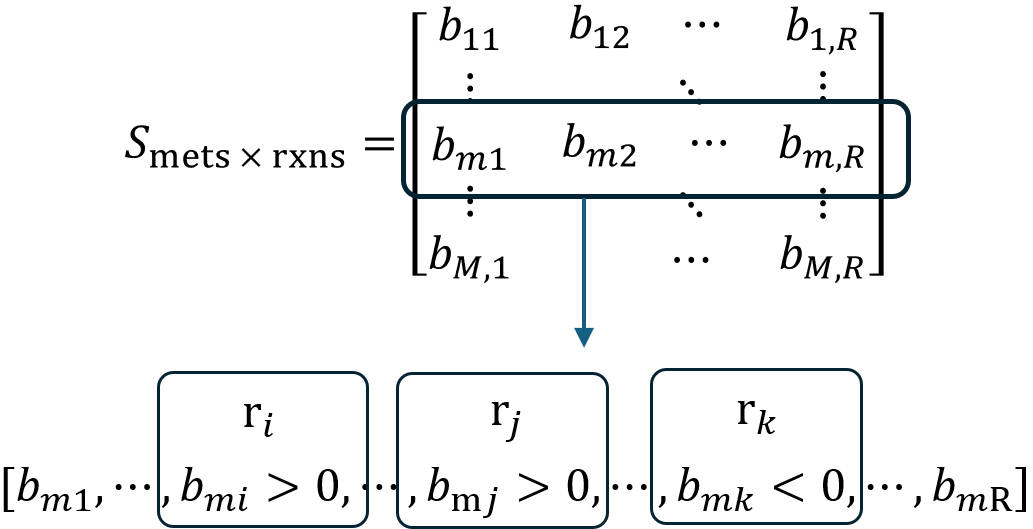

Fig. 2: Description of Step 1.

- **Step 2:** As represented in  Fig. 3, we look for the metabolites $\text{m}_2$ and $\text{m}_3$ that are produced by the same chemical reaction $r_1$ and are consumed by the  chemical reactions $r_2$ and $r_3$. In general, this step finds within the two chemical reactions from the above step (within the corresponding columns in the matrix S), two rows that produces the metabolites like  $m_2$ and $m_3$ with the same chemical reaction, like $r_1$ (Fig. 1), and those metabolites are also consumed by the chemical reactions $r_2$ and $r_3$. This step is divided into two sub-steps

- Step 2.1: Find the rows of the matrix S, where $r_2$ and $r_3$ consumes a metabolite

- Step 2.2: In those rows from Step 2.1, find those chemical reactions that produces that metabolite in the row.

- Step 2.3: Find the common index in those rows in Step 2.2 where they are both positive. This index identifies the chemical reaction $r_1$ like.

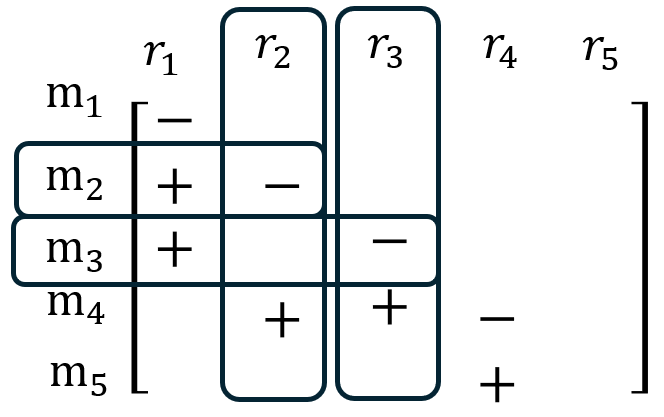

Fig. 3: Description of the Step 2.

#### Step 1


S = model.S;

% %testing matrix
% S=[-1  0  0  0  0,
%     1 -1  0  0  0,
%     1  0 -1  0  0,
%     0  1  1 -1  0,
%     0  0  0  0  0]
% 
% %testing matrix
% S=[ 1 -1  0  0  0,
%     1 -1  0  0  0,
%     1  0 -1  0  0,
%     0  1  1 -1  0,
%     0  0  0  0  0]
% 
% %testing matrix
% S=[ 1 -1  0  0  0,
%     1 -1  0  0  0,
%     1  0 -1  0  0,
%     0  1  1 -1  0,
%     1 -1 -1  0  0]

%% Optional: filter out "currency metabolites"
badMetPatterns = ["h[", "h2o[", "atp[", "adp[", "pi[", "ppi[", ...
                  "nad[", "nadh[", "nadp[", "nadph["];

isBadMet = false(numel(model.mets),1);
for k = 1:numel(badMetPatterns)
    isBadMet = isBadMet | contains(lower(string(model.mets)), badMetPatterns(k));
end

%% Helper functions for GPR interpretation

% A reaction is considered single-gene if its GPR rule:
% - is non-empty
% - contains no logical AND / OR operators
isSingleGeneRule = @(rule) ...
    strlength(rule) > 0 && ...
    ~contains(lower(rule), ' and ') && ...
    ~contains(lower(rule), ' or ');

% Extract gene identifiers appearing in a GPR rule (best-effort tokenization)
parseGeneList = @(rule) unique( ...
    regexp(rule, '[A-Za-z0-9_:\-\.]+', 'match') );

% Logical vector indicating whether each reaction is controlled by one gene
isSingleGene = false(numel(model.rxns),1);

%% Storage for motif results
results_Step_1 = [];
idx_motif = 1;
total_idx_motif=10E10;

% Scan per reaction a pattern, where a metabolite is consumed and at least
% N others are produced, but those producing the same metabolite

%% Scan each metabolite row in S for a 2-producer / 1-consumer junction

[met_total, reaction_total]=size(S);

%identifying those metabolites to avoid
m_H2O=find(contains(model.metNames,'H2O'));
m_H=find(contains(model.metNames,'H'));
m_ATP=find(contains(model.metNames,'ATP'));

for m = 1:met_total

    % if isBadMet(m)
    %     continue;
    % end

    %avoid a metabolite as water
    if(ismember(m,m_H2O) || ismember(m,m_H) || ismember(m,m_ATP))
        continue;
    end


    row = S(m,:);

    %find those reactions that produced the metabolite m
    producers = find(row > 0);
    %find those reactions that consumes the metabolite m
    consumers = find(row < 0);

    % % Keep only producers that are single-gene-controlled
    % producersSG = producers(isSingleGene(producers));

    % if numel(producersSG) < 2 || numel(consumers) < 1
    %     continue;
    % end

    %avoid those metabolites that are not produced by two separate chemical
    %reactions and consumed by a third one
    if numel(producers) < 2 || numel(consumers) < 1
        continue;
    end

    %storing those chemical reaction rates in results_Step_1
    %Evaluating the pairs of chemical reactions within the same metabolite
    r_pairs=nchoosek(producers,2);
    [r_total,~]=size(r_pairs);

    for i_r=1:r_total
        %% --- Gene information  ---
        %Only saving those reactions where a gene mediates
        % Raw GPR rule for reaction 2
        gpr2 = string(model.grRules{r_pairs(i_r,1)});
        % Extract all genes appearing in the GPR of reaction 2
        genes2 = strings(0,1);
        if strlength(gpr2) > 0
            genes2 = string(parseGeneList(gpr2))';
            genes2 = genes2(~ismember(lower(genes2), ["and","or"]));
        else
            continue;
        end

        % Raw GPR rule for reaction 3
        gpr3 = string(model.grRules{r_pairs(i_r,2)});
        % Extract all genes appearing in the GPR of reaction 1
        genes3 = strings(0,1);
        if strlength(gpr3) > 0
            genes3 = string(parseGeneList(gpr3))';
            genes3 = genes3(~ismember(lower(genes3), ["and","or"]));
        else
            continue;
        end

        %looking for those chemical reactions where different genes
        %mediates
        if(isequal(genes2,genes3))
            continue;
        end

        results_Step_1(idx_motif).m4=m;        
        results_Step_1(idx_motif).r2=r_pairs(i_r,1);
        results_Step_1(idx_motif).r3=r_pairs(i_r,2);    

        idx_motif=idx_motif+1;

        if (idx_motif==total_idx_motif)
            break;
        end

    end

    if (idx_motif==total_idx_motif)
        break;
    end
end

idx_Motif_1=1;
%% Convert results to a table for inspection
if isempty(results_Step_1)
    Motifs_Step_1 = table();
else
    Motifs_Step_1 = struct2table(results_Step_1);
end

Motifs_Step_1

Motifs_Step_1 = 29937×3 table
    m4    r2      r3 
    __    ___    ____

    19      3      78
    19      3     731
    19      3    3518
    19     78    3518
    19    731    3518
    20    869     923
    20    923    1324
    24    438     885
    26    439    4104
    27    443     847
    30    666     970
    49    555     939
    52    348     573
    52    348     875
    52    573     875
    54    347     958



fprintf('Metabolite m4: %s',string(model.metFormulas(Motifs_Step_1.m4(idx_Motif_1))));

Metabolite m4: C4H8O2


fprintf('Reaction 2: %s',string(model.rxnNames(Motifs_Step_1.r2(idx_Motif_1))));

Reaction 2: (R,R)-butanediol dehydrogenase

rxnFstr  = reactionToString_chm(model, Motifs_Step_1.r2(idx_Motif_1), true);
fprintf('  %s\n', rxnFstr);

  C4H10O2 + C21H26N7O14P2  ->  C4H8O2 + H + C21H27N7O14P2



fprintf('Reaction 3: %s',string(model.rxnNames(Motifs_Step_1.r3(idx_Motif_1))));

Reaction 3: acetaldehyde condensation

rxnFstr  = reactionToString_chm(model, Motifs_Step_1.r3(idx_Motif_1), true);
fprintf('  %s\n', rxnFstr);

  2 C2H4O  ->  C4H8O2


#### Step 2

%% Storage for motif results
results_Step_2 = [];
%Each column of represent a combination per item, for instance the first
%column tells the metabolites and chemical reactions that follows the
%structure in Fig.1, the second column another combination of metabolites
%and chemical reactions for the same structure, and so on.

idx_motif = 1;

R2=[results_Step_1.r2];
R3=[results_Step_1.r3];

%pick up the first metabolite in the repeating series of unique metabolites
% [values, first_indices] = unique(A, 'stable')
[~, idx_mets] = unique([results_Step_1.m4], 'stable');
% limit number of structures
limit_arch_met=1;%number of architectures per metabolite m4 %consider to stop on those architectures that are placed in the same place
count_arch_met=1;

number_arch=2;%number of architectures that has been found in total

%looping in the number of reactions r2 that produces metabolite m4
for i_r2_uniq=1:length(idx_mets)
    i_r2 = idx_mets(i_r2_uniq);

    %stop with the number or architectures are met
    if(idx_motif>number_arch)
        break;
    end

    %Step 2.1: Find the rows of the matrix S, where r_2 consumes a metabolite
    met_consumer_r2 = find(S(:,R2(i_r2))<0);

    %looping in the number of reactions r3 that produces metabolite m4
    % for i_r3=1:length(R3)
    %     %Avoiding the same chemical reactions r2 and r3
    %     if(i_r3==i_r2)
    %         continue;
    %     end

        %Step 2.1: Find the rows of the matrix S, where r_3 consumes a metabolite
        met_consumer_r3=find(S(:,results_Step_1(i_r2).r3)<0);
        
        %looping on those consumed metabolites by reaction r2
        for i_m_r2=1:length(met_consumer_r2)
            %looping on those consumed metabolites by reaction r3
            for i_m_r3=1:length(met_consumer_r3)
                
                %Avoiding the same metabolites m2 and m3
                if(i_m_r3==i_m_r2)
                    continue;
                end


                %Step 2.2: In those rows from Step 2.1, find those chemical reactions that produces that metabolite in the row.
                idx_met_r2=met_consumer_r2(i_m_r2);
                idx_met_r3=met_consumer_r3(i_m_r3);
                reaction_producer_r2=find(S(idx_met_r2,:)>0);
                reaction_producer_r3=find(S(idx_met_r3,:)>0);
        
                %Avoiding metabolites of water and hydrogen
                if(ismember(idx_met_r2,m_H2O) || ismember(idx_met_r2,m_H) || ismember(idx_met_r2,m_ATP) || ...
                   ismember(idx_met_r3,m_H2O) || ismember(idx_met_r3,m_H) || ismember(idx_met_r3,m_ATP))
                    continue;
                end
                %Avoiding the same consumed metabolite
                if(idx_met_r2==idx_met_r3)
                    continue;
                end

                %Step 2.3: Find the common index in the two rows in Step 2.2 where both metabolites are positive.
                % This index identifies the chemical reaction  like.
                reaction_producer_r1=intersect(reaction_producer_r2,reaction_producer_r3);
        
                 %avoiding reactions r2 and r3 with the same gene
                 r2=results_Step_1(i_r2).r2;
                 r3=results_Step_1(i_r2).r3;
                 gpr2=model.grRules{r2};
                 gpr3=model.grRules{r3};
                 if(ismember(gpr2,gpr3))
                     continue;
                 end

                if(~isempty(reaction_producer_r1))
                    for i=1:length(reaction_producer_r1)
                        % Removing those reactions of zero genes
                        % Raw GPR rule for reaction 3
                        gpr1 = string(model.grRules{reaction_producer_r1(i)});
                        % Extract all genes appearing in the GPR of reaction 1
                        genes1 = strings(0,1);
                        if strlength(gpr1) > 0
                            genes1 = string(parseGeneList(gpr1))';
                            genes1 = genes1(~ismember(lower(genes1), ["and","or"]));
                        else
                            continue;
                        end
                       
                        %avoiding reaction r1 with same genes as r2 or r3
                        if(ismember(gpr1,gpr2) || ismember(gpr1,gpr3))
                            continue;
                        end

                        %saving the results
                        %Related to the output metabolite fo reaction 1 and 2
                        results_Step_2(idx_motif).m4=results_Step_1(i_r2).m4;
                        

                        %Info related to reaction 2
                        results_Step_2(idx_motif).r2=results_Step_1(i_r2).r2;                        
                        results_Step_2(idx_motif).m2=met_consumer_r2(i_m_r2);
                        

                        %Info related to reaction 3
                        results_Step_2(idx_motif).r3=results_Step_1(i_r2).r3;
                        results_Step_2(idx_motif).m3=met_consumer_r3(i_m_r3);
                       

                        %Info related to reaction 1
                        results_Step_2(idx_motif).r1=reaction_producer_r1(i);
                        

                        idx_motif=idx_motif+1;
                        
                        if(count_arch_met>limit_arch_met)
                            break;
                        end

                        count_arch_met=count_arch_met+1;
                    end                    
                end
                if(count_arch_met>limit_arch_met)
                    break;
                end
            end
            if(count_arch_met>limit_arch_met)
                break;
            end
        end
        if(count_arch_met>limit_arch_met)
            count_arch_met=1;
        end
    % end
    % if(count_arch_met>limit_arch_met)
    %     count_arch_met=1;       
    % end
end


idx_Motif_2=1;
%% Convert results to a table for inspection
if isempty(results_Step_1)
    Motifs_Step_2 = table();
else
    Motifs_Step_2 = struct2table(results_Step_2);
end



fprintf('\n=============================\n');

fprintf(' Motif_Step_2 row: %d\n', idx_Motif_2);

 Motif_Step_2 row: 1


fprintf('=============================\n');


m2=(Motifs_Step_2.m2(idx_Motif_2));
m3=(Motifs_Step_2.m3(idx_Motif_2));
m4=(Motifs_Step_2.m4(idx_Motif_2));

fprintf('Metabolite m2: Formula: %s | Name: %s| %s   | ID: %s ', string(model.metFormulas(m2)),...
                                                                   string(model.metNames(m2)), ...
                                                                   string(m2), ...
                                                                   string(model.mets(m2)));

Metabolite m2: Formula: C21H32N7O16P3S | Name: coenzyme A| 405   | ID: s_0534 


fprintf('Metabolite m3: Formula: %s | Name: %s| %s   | ID: %s ', string(model.metFormulas(m3)),...
                                                                   string(model.metNames(m3)), ...
                                                                   string(m3), ...
                                                                   string(model.mets(m3)));

Metabolite m3: Formula: C10H19O2 | Name: decanoate| 460   | ID: s_0600 


fprintf('Metabolite m4: Formula: %s | Name: %s| %s   | ID: %s ', string(model.metFormulas(m4)),...
                                                                   string(model.metNames(m4)), ...
                                                                   string(m4), ...
                                                                   string(model.mets(m4)));

Metabolite m4: Formula: C31H50N7O17P3S | Name: decanoyl-CoA| 461   | ID: s_0605 


% reactionToString_chm(model, Motifs_Step_2.r2(idx), false);

r1=Motifs_Step_2.r1(idx_Motif_2);
fprintf('Reaction 1: %s',string(model.rxnNames(r1)));

Reaction 1: peroxisomal acyl-CoA thioesterase

rxnFstr  = reactionToString_chm(model, r1, true);
fprintf('  %s\n', rxnFstr);

  C31H50N7O17P3S + H2O  ->  C21H32N7O16P3S + C10H19O2 + H


fprintf('  Genes:  %s\n', string(model.grRules(r1)));

  Genes:  YJR019C


getReactionLocationString(model,r1)

ans = "peroxisome"

fprintf(' Location: %s\n', getReactionLocationString(model,r1));

 Location: peroxisome


fprintf(' EC code: %s\n', string(model.eccodes(r1)));

 EC code: 3.1.2.2



r2=Motifs_Step_2.r2(idx_Motif_2);
fprintf('Reaction 2: %s',string(model.rxnNames(r2)));

Reaction 2: acetyl-CoA C-acyltransferase (decanoyl-CoA)

rxnFstr  = reactionToString_chm(model, r2, true);
fprintf('  %s\n', rxnFstr);

  C33H52N7O18P3S + C21H32N7O16P3S  ->  C23H34N7O17P3S + C31H50N7O17P3S


fprintf('  Genes:  %s\n', string(model.grRules(r2)));

  Genes:  YIL160C


fprintf(' Location: %s\n', getReactionLocationString(model,r2));

 Location: peroxisome


fprintf(' EC code: %s\n', string(model.eccodes(r2)));

 EC code: 2.3.1.16



r3=Motifs_Step_2.r3(idx_Motif_2);
fprintf('Reaction 3: %s',string(model.rxnNames(r3)));

Reaction 3: fatty-acid--CoA ligase (decanoate)

rxnFstr  = reactionToString_chm(model, r3, true);
fprintf('  %s\n', rxnFstr);

  C10H12N5O13P3 + C21H32N7O16P3S + C10H19O2  ->  C10H12N5O7P + C31H50N7O17P3S + HO7P2


fprintf('  Genes:  %s\n', string(model.grRules(r3)));

  Genes:  YER015W


fprintf(' Location: %s\n', getReactionLocationString(model,r3));

 Location: peroxisome


fprintf(' EC code: %s\n', string(model.eccodes(r3)));

 EC code: 6.2.1.3


## ---------------- Helper functions ----------------

function printMotifLine_Step2(model, Motifs_Step_2, idx)
% printMotifLine_Step2
%
% Prints a selected line (row) from Motifs_Step_2 with:
%   - adder metabolite (m4) name + formula
%   - the key "output"/junction metabolites (m2, m3) if present
%   - reactions r1, r2, r3 as:
%       1) metabolite-ID equation
%       2) chemical-formula equation
%       3) GPR rule (as stored in Motifs_Step_2.gpr*)
%       4) EC code (from model.eccodes, if present)
%       5) Location + Subsystem (if present in model)
%
% Requirements:
%   - You already have the helper functions you posted earlier:
%       reactionToString_chm, getReactionLocationString, getReactionSubsystemString
%   - Motifs_Step_2 is built from results_Step_2 via struct2table.

fprintf('\n=============================\n');
fprintf(' Motif_Step_2 row: %d\n', idx);
fprintf('=============================\n');

% ---------- Adder metabolite m4 ----------
m4idx  = getMetIndexFlexible(Motifs_Step_2, idx, "m4");
m4name = string(model.metNames(m4idx)); %safeGetString(Motifs_Step_2, idx, "m4_name");
m4id   = metIDfromIndex(model, m4idx);
m4f    = metFormulaFromIndex(model, m4idx);

fprintf('Metabolite m4: %s', m4id);
if strlength(m4name) > 0, fprintf('  | name: %s', m4name); end
if strlength(m4f)    > 0, fprintf('  | formula: %s', m4f); end
fprintf('\n');

% ---------- Optional: junction/output metabolites m2, m3 ----------
printMetLineIfExists(model, Motifs_Step_2, idx, "m2", "m2_string", "Metabolite m2");
printMetLineIfExists(model, Motifs_Step_2, idx, "m3", "m3_string", "Metabolite m3");
fprintf('\n');

% ---------- Reactions r1, r2, r3 ----------
printOneRxnBlock(model, Motifs_Step_2, idx, "r1", "r1_string", "gpr1", "r1");
printOneRxnBlock(model, Motifs_Step_2, idx, "r2", "r2_string", "gpr2", "r2");
printOneRxnBlock(model, Motifs_Step_2, idx, "r3", "r3_string", "gpr3", "r3");



fprintf('\n');
end

%% ---------------- Helper functions (NEW) ----------------

function printOneRxnBlock(model, T, idx, rxnField, rxnNameField, gprField, label)
% Prints a single reaction block from the table row.

rxnIdx = getRxnIndexFlexible(model, T, idx, rxnField, rxnNameField);

fprintf('%s: ', label);

% Try to print a reaction identifier (model.rxns entry if index is known)
if ~isempty(rxnIdx)
    fprintf('%s', string(model.rxns{rxnIdx}));
else
    % fall back to stored string if present
    rxnIDmaybe = safeGetString(T, idx, rxnField);
    if strlength(rxnIDmaybe) == 0
        rxnIDmaybe = safeGetString(T, idx, rxnNameField);
    end
    if strlength(rxnIDmaybe) == 0
        fprintf('(unknown reaction)');
    else
        fprintf('%s', rxnIDmaybe);
    end
end

% Optional: human name
rxnName = safeGetString(T, idx, rxnNameField);
if strlength(rxnName) > 0 && ~(rxnName == "(missing)")
    fprintf('  | name: %s', rxnName);
end
fprintf('\n');

if isempty(rxnIdx)
    fprintf('  (reaction not found in model)\n\n');
    return;
end

% 1) Chemical reaction with metabolite IDs
rxnIDstr = reactionToString_chm(model, rxnIdx, false);
fprintf('  %s\n', rxnIDstr);

% 2) Chemical reaction with formulas
rxnFstr  = reactionToString_chm(model, rxnIdx, true);
fprintf('  %s\n', rxnFstr);

% 3) GPR rule (print EXACT rule, as requested)
gpr = safeGetString(T, idx, gprField);
if strlength(gpr) == 0 || gpr == "(missing)"
    % fall back to model.grRules if you didn't store it in the table row
    if isfield(model,'grRules') && numel(model.grRules) >= rxnIdx && ~isempty(model.grRules{rxnIdx})
        gpr = string(model.grRules{rxnIdx});
    else
        gpr = "";
    end
end

if strlength(gpr) > 0
    fprintf('  GPR: %s\n', gpr);
else
    fprintf('  GPR: none annotated\n');
end

% 4) EC codes (if available)
if isfield(model,'eccodes') && numel(model.eccodes) >= rxnIdx && ~isempty(model.eccodes{rxnIdx})
    fprintf('  EC: %s\n', string(model.eccodes{rxnIdx}));
else
    fprintf('  EC: none annotated\n');
end

% 5) Location + Subsystem (if your earlier helpers are in path)
try
    fprintf('  Location: %s\n', getReactionLocationString(model, rxnIdx));
catch
    % ignore if helper not present
end

try
    fprintf('  Subsystem: %s\n', getReactionSubsystemString(model, rxnIdx));
catch
    % ignore if helper not present
end

fprintf('\n');
end

function rxnIdx = getRxnIndexFlexible(model, T, idx, rxnField, rxnNameField)
% Tries hard to convert what's stored in T.(rxnField) / T.(rxnNameField)
% into a reaction index in model.rxns.
%
% Works if T stores:
%   - numeric reaction indices
%   - reaction IDs that exist in model.rxns
%   - reaction names that exist in model.rxnNames (fallback)

rxnIdx = [];

% 1) If rxnField is numeric, treat as direct index
if ismember(rxnField, T.Properties.VariableNames)
    val = T.(rxnField)(idx,:);
    if isnumeric(val) && isscalar(val) && ~isnan(val) && val >= 1 && val <= numel(model.rxns)
        rxnIdx = double(val);
        return;
    end
end

% 2) Try rxnField as a reaction ID string in model.rxns
rxnID = safeGetString(T, idx, rxnField);
if strlength(rxnID) > 0 && rxnID ~= "(missing)"
    hit = find(strcmp(model.rxns, rxnID), 1);
    if ~isempty(hit)
        rxnIdx = hit;
        return;
    end
end

% 3) Try rxnNameField as reaction ID (sometimes people store IDs there)
rxnID2 = safeGetString(T, idx, rxnNameField);
if strlength(rxnID2) > 0 && rxnID2 ~= "(missing)"
    hit = find(strcmp(model.rxns, rxnID2), 1);
    if ~isempty(hit)
        rxnIdx = hit;
        return;
    end
end

% 4) Try rxnNameField as reaction name in model.rxnNames (if available)
if isfield(model,'rxnNames') && ismember(rxnNameField, T.Properties.VariableNames)
    rxnName = safeGetString(T, idx, rxnNameField);
    if strlength(rxnName) > 0 && rxnName ~= "(missing)"
        hit = find(strcmp(string(model.rxnNames), rxnName), 1);
        if ~isempty(hit)
            rxnIdx = hit;
            return;
        end
    end
end
end

function mIdx = getMetIndexFlexible(T, idx, metField)
% Reads a metabolite index from T.(metField) if present.
mIdx = [];
if ismember(metField, T.Properties.VariableNames)
    v = T.(metField)(idx,:);
    if isnumeric(v) && isscalar(v) && ~isnan(v)
        mIdx = double(v);
    end
end
end

function printMetLineIfExists(model, T, idx, metField, metStrField, label)
% Prints a metabolite line if the table contains the requested fields.
mIdx = getMetIndexFlexible(T, idx, metField);

metID = "";
metF  = "";
if ~isempty(mIdx) && mIdx >= 1 && mIdx <= numel(model.mets)
    metID = string(model.mets{mIdx});
    metName = string(model.metNames{mIdx});
    metF  = metFormulaFromIndex(model, mIdx);
else
    % fall back to stored string if provided
    metID = safeGetString(T, idx, metStrField);
end

if strlength(metID) == 0 || metID == "(missing)"
    return;
end

fprintf('%s: %s | %s', label, metID, metName);
if strlength(metF) > 0
    fprintf('  | formula: %s', metF);
end
fprintf('\n');
end

function s = safeGetString(T, idx, fieldName)
% Safely fetches T.(fieldName)(idx) as string; returns "(missing)" if absent.
s = "(missing)";
if ~ismember(fieldName, T.Properties.VariableNames)
    return;
end
try
    v = T.(fieldName)(idx,:);
    if iscell(v)
        v = v{1};
    end
    s = string(v);
    if ismissing(s), s = ""; end
catch
    s = "(missing)";
end
end

function metID = metIDfromIndex(model, mIdx)
% Returns metabolite ID from index, else empty.
metID = "";
if ~isempty(mIdx) && mIdx >= 1 && mIdx <= numel(model.mets)
    metID = string(model.mets{mIdx});
end
end

function metF = metFormulaFromIndex(model, mIdx)
% Returns formula from index if available, else empty.
metF = "";
if ~isempty(mIdx) && isfield(model,'metFormulas') && numel(model.metFormulas) >= mIdx ...
        && ~isempty(model.metFormulas{mIdx})
    metF = string(model.metFormulas{mIdx});
end
end

% function printMotifReactionsWithFormulas(model, Motifs, idx)
% % printMotifReactionsWithFormulas
% %
% % Prints reactions associated with one Motifs row in the following order:
% %   1) reaction with metabolite IDs
% %   2) reaction with chemical formulas
% %   3) associated gene(s)
% %   4) associated enzyme EC code(s)
% 
% fprintf('\n=== Motif %d ===\n', idx);
% fprintf('Adder metabolite: %s (%s)\n\n', Motifs.m4(idx),string(model.metFormulas(Motifs.m4(idx))));
% 
% rxnNames  = {Motifs.r2_Name(idx), Motifs.r3_Name(idx)};
% rxnLabels = {'r2 (input)', 'r3  (input)'};
% 
% for k = 1:numel(rxnNames)
% 
%     rxnID = rxnNames{k};
%     r = find(strcmp(model.rxns, rxnID));
% 
%     if isempty(r)
%         fprintf('%s: reaction not found\n\n', rxnLabels{k});
%         continue;
%     end
% 
%     fprintf('%s: %s\n', rxnLabels{k}, rxnID);
% 
%     % 1) Reaction using metabolite IDs
%     rxnIDstr = reactionToString_chm(model, r, false);
%     fprintf('%s\n', rxnIDstr);
% 
%     % 2) Reaction using chemical formulas
%     rxnFstr = reactionToString_chm(model, r, true);
%     fprintf('%s\n', rxnFstr);
% 
%     % 3) Gene information
%     geneStr = getReactionGeneString(model, r);
%     if strlength(geneStr) == 0
%         fprintf('gene(s): none annotated\n');
%     else
%         fprintf('%s\n', geneStr);
%     end
% 
%     % 4) Enzyme EC code(s)
%     if isfield(model,'eccodes') && numel(model.eccodes) >= r ...
%             && ~isempty(model.eccodes{r})
%         fprintf('EC: %s\n', model.eccodes{r});
%     else
%         fprintf('EC: none annotated\n');
%     end
% 
%     fprintf('\n');
% end
% end

function rxnStr = reactionToString_chm(model, r, useFormula)
% Converts reaction r into a readable chemical equation.
% useFormula = false → metabolite IDs; true → chemical formulas (if available).

col = model.S(:,r);
metIdx = find(col ~= 0);

reactants = {};
products  = {};

for i = 1:numel(metIdx)
    m = metIdx(i);
    coeff = full(col(m));

    if useFormula
        metName = getMetFormula(model, m);
    else
        metName = string(model.mets{m});
    end

    if coeff < 0
        reactants{end+1} = formatTerm(-coeff, metName); %#ok<AGROW>
    elseif coeff > 0
        products{end+1}  = formatTerm(coeff, metName);  %#ok<AGROW>
    end
end

lhs = strjoinOrEmpty(reactants);
rhs = strjoinOrEmpty(products);

rxnStr = sprintf('%s  ->  %s', lhs, rhs);
end

function f = getMetFormula(model, m)
% Returns chemical formula for metabolite m if available, else metabolite ID.
if isfield(model,'metFormulas') && numel(model.metFormulas) >= m && ~isempty(model.metFormulas{m})
    f = string(model.metFormulas{m});
else
    f = string(model.mets{m});
end
end

function term = formatTerm(coeff, name)
% Formats a term like "ATP[c]" or "2 ATP[c]"
if abs(coeff - 1) < 1e-9
    term = string(name);
else
    term = sprintf('%g %s', coeff, string(name));
end
end

function s = strjoinOrEmpty(list)
% Joins terms with " + " or returns the empty symbol if list is empty.
if isempty(list)
    s = '∅';
else
    s = strjoin(string(list), ' + ');
end
end

function geneStr = getReactionGeneString(model, r)
% Returns "gene: X" or "gene(s): A;B;C" or "" if none annotated.

genes = strings(0,1);

% Preferred: rxnGeneMat
if isfield(model,'rxnGeneMat') && ~isempty(model.rxnGeneMat) && isfield(model,'genes')
    gIdx = find(model.rxnGeneMat(r,:));
    if ~isempty(gIdx)
        genes = string(model.genes(gIdx));
    end
end

% Fallback: parse grRules
if isempty(genes) && isfield(model,'grRules') && numel(model.grRules) >= r
    rule = string(model.grRules{r});
    if strlength(rule) > 0
        toks = regexp(rule, '[A-Za-z0-9_:\-\.]+', 'match');
        toks = unique(string(toks));
        toks = toks(~ismember(lower(toks), ["and","or"]));
        genes = toks;
    end
end

if isempty(genes)
    geneStr = "";
    return;
end

if numel(genes) == 1
    geneStr = sprintf('gene: %s', genes(1));
else
    geneStr = sprintf('gene(s): %s', strjoin(genes, ';'));
end
end

function locStr = getReactionLocationString(model, r)
% Infers compartments involved in reaction r from participating metabolites,
% then maps to human-readable names using model.compNames (if available).
%
% Returns a semicolon-separated string of compartment names (or IDs).

metIdx = find(model.S(:,r) ~= 0);

% Try the most reliable way first: model.metComps (index into model.comps)
compIDs = strings(0,1);

if isfield(model,'metComps') && ~isempty(model.metComps) && isfield(model,'comps')
    cIdx = unique(model.metComps(metIdx));
    compIDs = string(model.comps(cIdx));
else
    % Fallback: parse compartment tags like "glc6p[c]" → "c"
    mets = string(model.mets(metIdx));
    tags = regexp(mets, '\[([^\]]+)\]', 'tokens', 'once');
    tags = tags(~cellfun(@isempty, tags));
    if ~isempty(tags)
        compIDs = unique(string([tags{:}]));
    end
end

if isempty(compIDs)
    locStr = "unknown";
    return;
end

% Map compartment IDs to compartment names if available
if isfield(model,'compNames') && isfield(model,'comps') && ~isempty(model.compNames)
    comps = string(model.comps);
    compNames = string(model.compNames);

    names = strings(size(compIDs));
    for i = 1:numel(compIDs)
        j = find(comps == compIDs(i), 1);
        if ~isempty(j) && j <= numel(compNames) && strlength(compNames(j)) > 0
            names(i) = compNames(j);
        else
            names(i) = compIDs(i); % fallback
        end
    end
    locStr = strjoin(unique(names), '; ');
else
    locStr = strjoin(unique(compIDs), '; ');
end
end

function subStr = getReactionSubsystemString(model, r)
% Returns the subsystem annotation for reaction r.
% Handles common storage types: cell array, string array, or missing.

subStr = "unknown";

if isfield(model,'subSystems') && ~isempty(model.subSystems)
    ss = model.subSystems;

    if iscell(ss)
        if numel(ss) >= r && ~isempty(ss{r})
            subStr = string(ss{r});
        end
    else
        % string array / categorical / char array variants
        try
            if numel(ss) >= r
                subStr = string(ss(r));
            end
        catch
            % leave as unknown
        end
    end
end
end

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end
